# Load Data, fm=2seg

%load('data.mat')
%load('DataDouble.mat')

# Plot Data

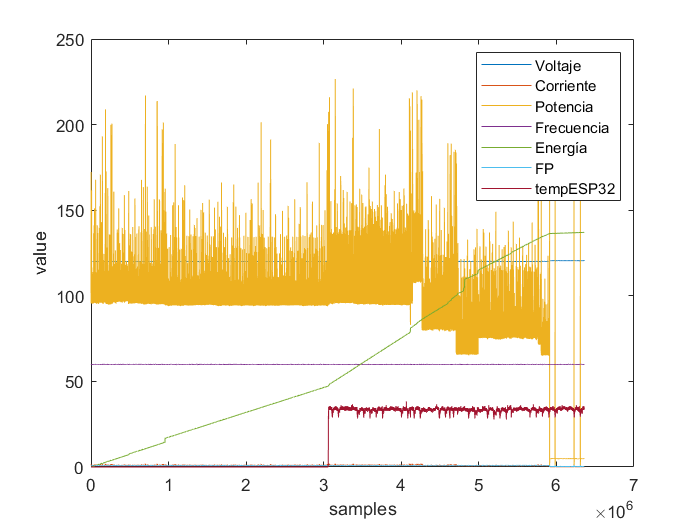

figure
plot(dataNew);xlabel('samples');ylabel('value');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energía','FP','tempESP32');

Input output Data

training=0.7;
testing=0.3;
% inputs: 'Voltaje','Corriente','Potencia','Frecuencia','Energía','FP','tempESP32'
input=dataNew(1:round(length(dataNew)*training)-1,:);
% output: Energía in the following time step
output=dataNew(2:round(length(dataNew)*training),5);